# Yacht hydrodynamics regression: held-out evaluation

This Live Script evaluates saved publication models through the current BANFF architecture. It reports the same task-level statistics and diagnostic plot families as the older task-specific implementation.

clearvars; close all; clc;

## Locate the publication code

evaluation_directory = fileparts(mfilename('fullpath'));
repository_root = fileparts(evaluation_directory);
addpath(repository_root, evaluation_directory);

## Choose the saved experiment family

Use the same profile and scientific overrides that were used for training.

seeds = 1:3;
profile = "main";            % main, full_rank, spsa, or neuron_sweep
overrides = struct();         % e.g. struct('N_hidden',8000) for neuron_sweep

## Choose display and export behaviour

display_options = struct();
display_options.representative_seed_index = 1;
display_options.representative_initial_condition = 1;
display_options.replay_static_spikes = true;
display_options.save_figures = false;
display_options.output_directory = fullfile(repository_root, ...
    'outputs', 'evaluation', 'yacht');

## Run held-out testing, statistics, seed audit, and plots


BANFF held-out test evaluation: yacht (main profile)
Seeds: [1 2 3]

Per-seed held-out test results
    Seed      Loss       RMSE     PearsonR     PearsonP     SignedErrorMean    SignedErrorStd    ActiveNeuronPercent
    ____    ________    ______    ________    __________    _______________    ______________    ___________________

     1      0.042786    4.5826     0.9536     1.6857e-33        -1.1199            4.4793              93.853       
     2      0.027091    3.6464    0.97239      2.936e-40       -0.85965            3.5721              83.128       
     3      0.030403    3.8629    0.96544     2.5109e-37        -0.2996            3.8822              84.009       

Across-seed mean and sample SD
         

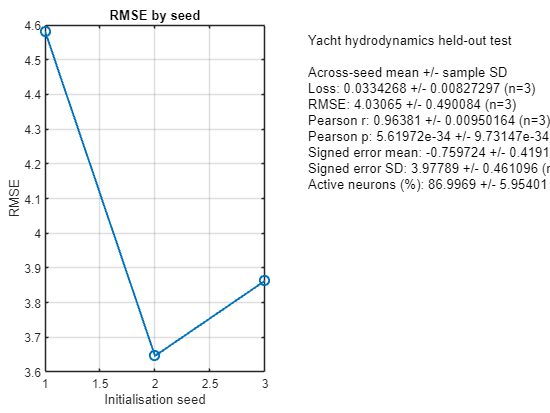

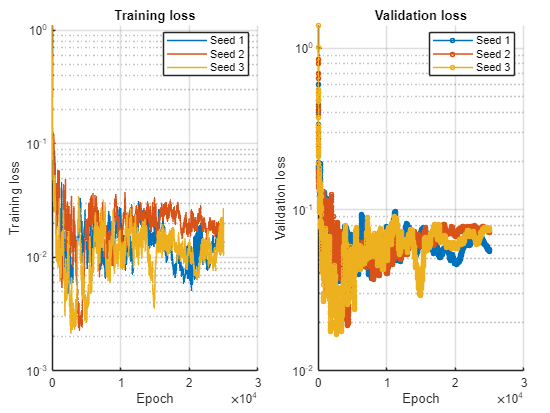

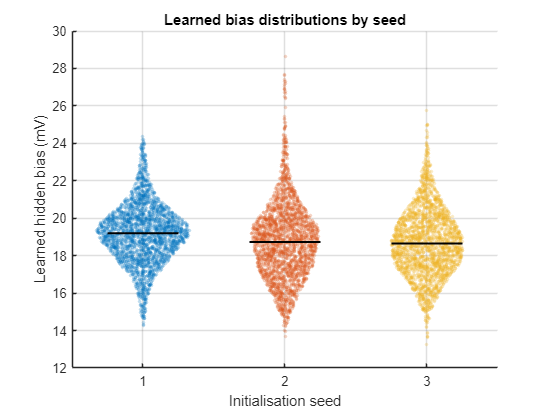

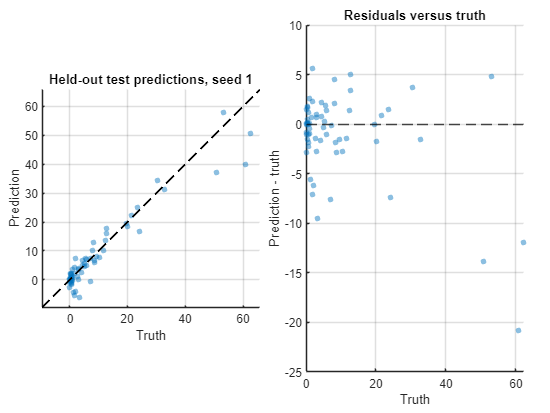

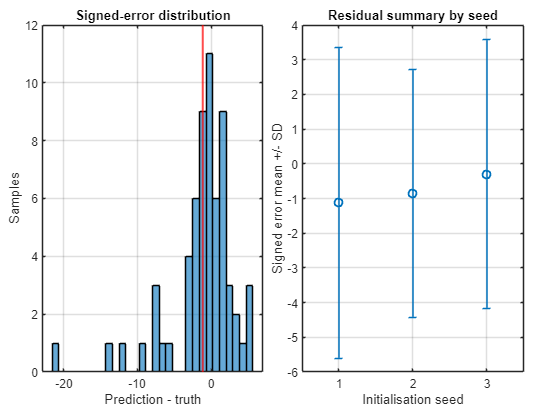

Exact full-held-out test current magnitudes (RMS over neurons, samples and time)
     Condition     EncoderRmsMv    NetRecurrentRmsMv    RecurrentToEncoderRms    GrossEncoderRmsMv    GrossRecurrentRmsMv    NetToGrossRecurrentRms    NetToGrossEncoderRms    AdaptationRmsMv    BiasDeviationRmsMv    DecoderContributionRms
    ___________    ____________    _________________    _____________________    _________________    ___________________    ______________________    ____________________    _______________    __________________    ______________________

    "Untrained"        1.99             0.50182                0.2

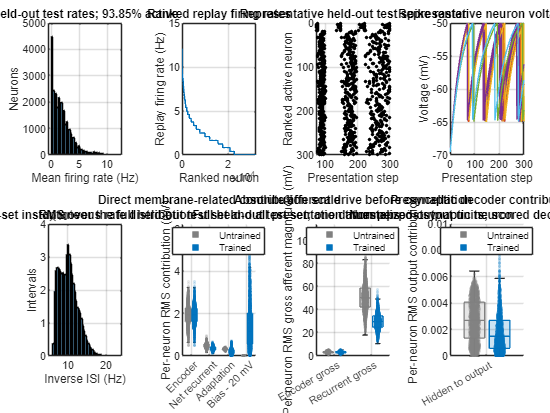

Current comparison: all 63 held-out test samples and 300 presentation steps (18900 observations per neuron and condition).


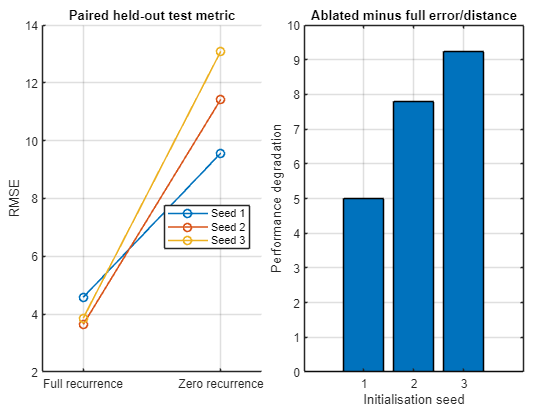

report = banff_evaluate_task("yacht", seeds, profile, overrides, display_options);

## Machine-readable results

report.seed_table

ans = 3×8 table
    Seed      Loss       RMSE     PearsonR     PearsonP     SignedErrorMean    SignedErrorStd    ActiveNeuronPercent
    ____    ________    ______    ________    __________    _______________    ______________    ___________________

     1      0.042786    4.5826     0.9536     1.6857e-33        -1.1199            4.4793              93.853       
     2      0.027091    3.6464    0.97239      2.936e-40       -0.85965            3.5721              83.128       
     3      0.030403    3.8629    0.96544     2.5109e-37        -0.2996            3.8822              84.009       


report.summary_table

ans = 7×4 table
           Metric               Mean        SampleSD     FiniteN
    _____________________    __________    __________    _______

    "Loss"                     0.033427      0.008273       3   
    "RMSE"                       4.0306       0.49008       3   
    "PearsonR"                  0.96381     0.0095016       3   
    "PearsonP"               5.6197e-34    9.7315e-34       3   
    "SignedErrorMean"          -0.75972       0.41919       3   
    "SignedErrorStd"             3.9779        0.4611       3   
    "ActiveNeuronPercent"        86.997         5.954       3   


report.network_seed_audit

ans = 3×4 table
    Seed                                                             ModelFile                                                                                       CheckpointHash                                                    FixedNetworkProbeHash                       
    ____    ___________________________________________________________________________________________________________________________    __________________________________________________________________    __________________________________________________________________

     1      "/home/kai.mason/Documents/BANFF_SNN_pub/outputs/models/yacht_eprop_low_rank_hard_spike_N32000_cfge3be149d02f1_seed001.mat"    "19760b5268607cff3030659cd48de9b8c11ff8b4c9fa22f2abc29452df0bd1a3"    "8a03c9aaadeea75965e2aaf6a814128d01ed96aed177397bd05985505402d3f2"
     2      "/home/